# Sulcal Pattern data on Manifolds (trees on manifold)

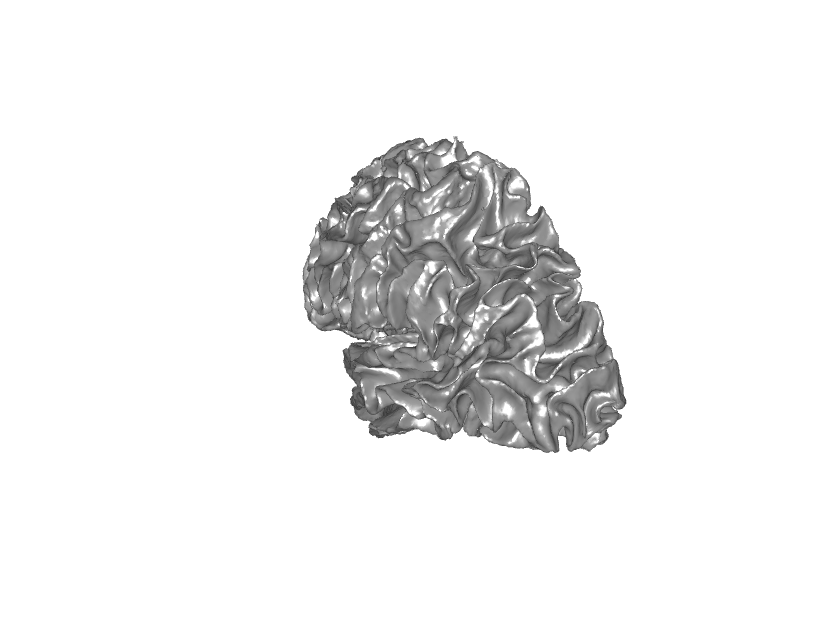

% Sulcal pattern data published in
%
% Huang, S.-G., Lyu, I., Qiu, A., Chung, M.K. 2020. 
% Fast polynomial approximation of heat kernel convolution 
% on manifolds and its application to brain sulcal and 
% gyral graph pattern analysis, IEEE Transactions on 
% Medical Imaging 39:2201-2212  arXiv 1911.02721
%
% If you are using data/codes, cite this paper
%
% (C) 2025 Moo K. Chung
% University of Wisconsin-Madison
% Last update: 2025 Jan 22; 2026 Feb 9 made into .mlx

load sulcalpattern.mat
surface_display_mono(whiteL)

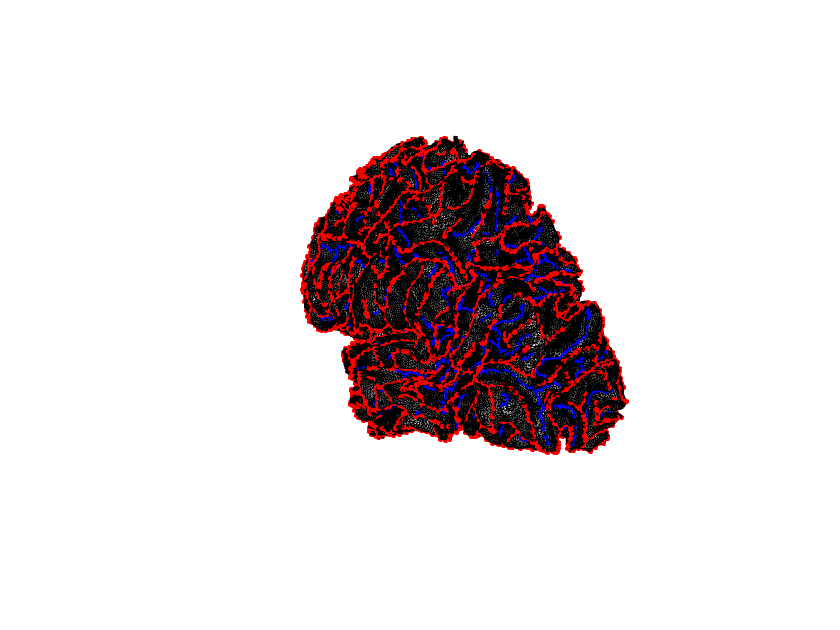

surface_display_mono(whiteL, 'k')
hold on; scurve_display(whiteL, gcurve,'r', 1.5) %display gyral graph edges
hold on; scurve_displaynodes(whiteL, gcurve,'r',3) %display graph nodes
hold on; scurve_display(whiteL, scurve, 'b', 1.5) %display sulcal graphs
hold on; scurve_displaynodes(whiteL, scurve,'b',3) %display graph nodes

## Spherical Mapping

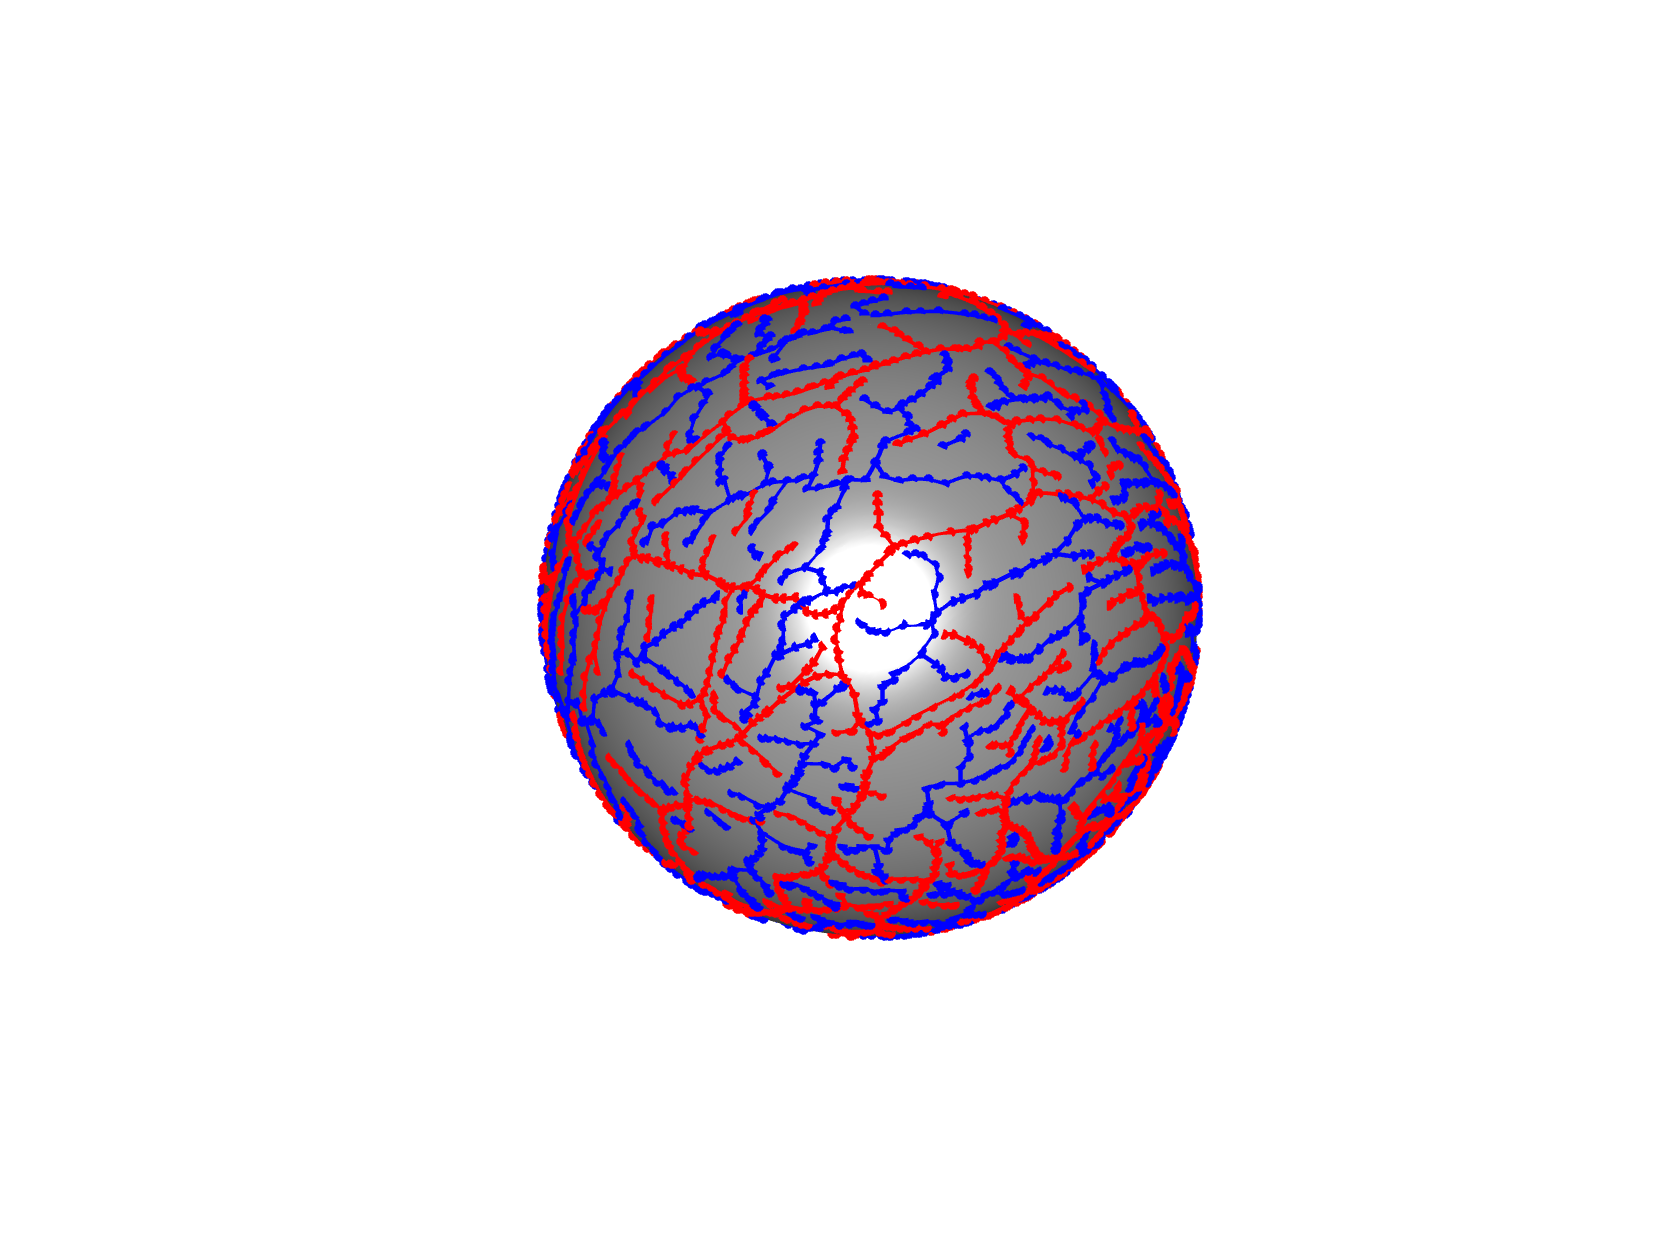

%The pattern is difficult to visualize so we map onto a sphere. 
surface_display_mono(sphereL)
hold on; scurve_display(sphereL, gcurve,'r', 1.5) %display gyral graph edges
hold on; scurve_displaynodes(sphereL, gcurve,'r',3) %display graph nodes
hold on; scurve_display(sphereL, scurve, 'b', 1.5) %display sulcal graphs
hold on; scurve_displaynodes(sphereL, scurve,'b',3) %display graph nodes

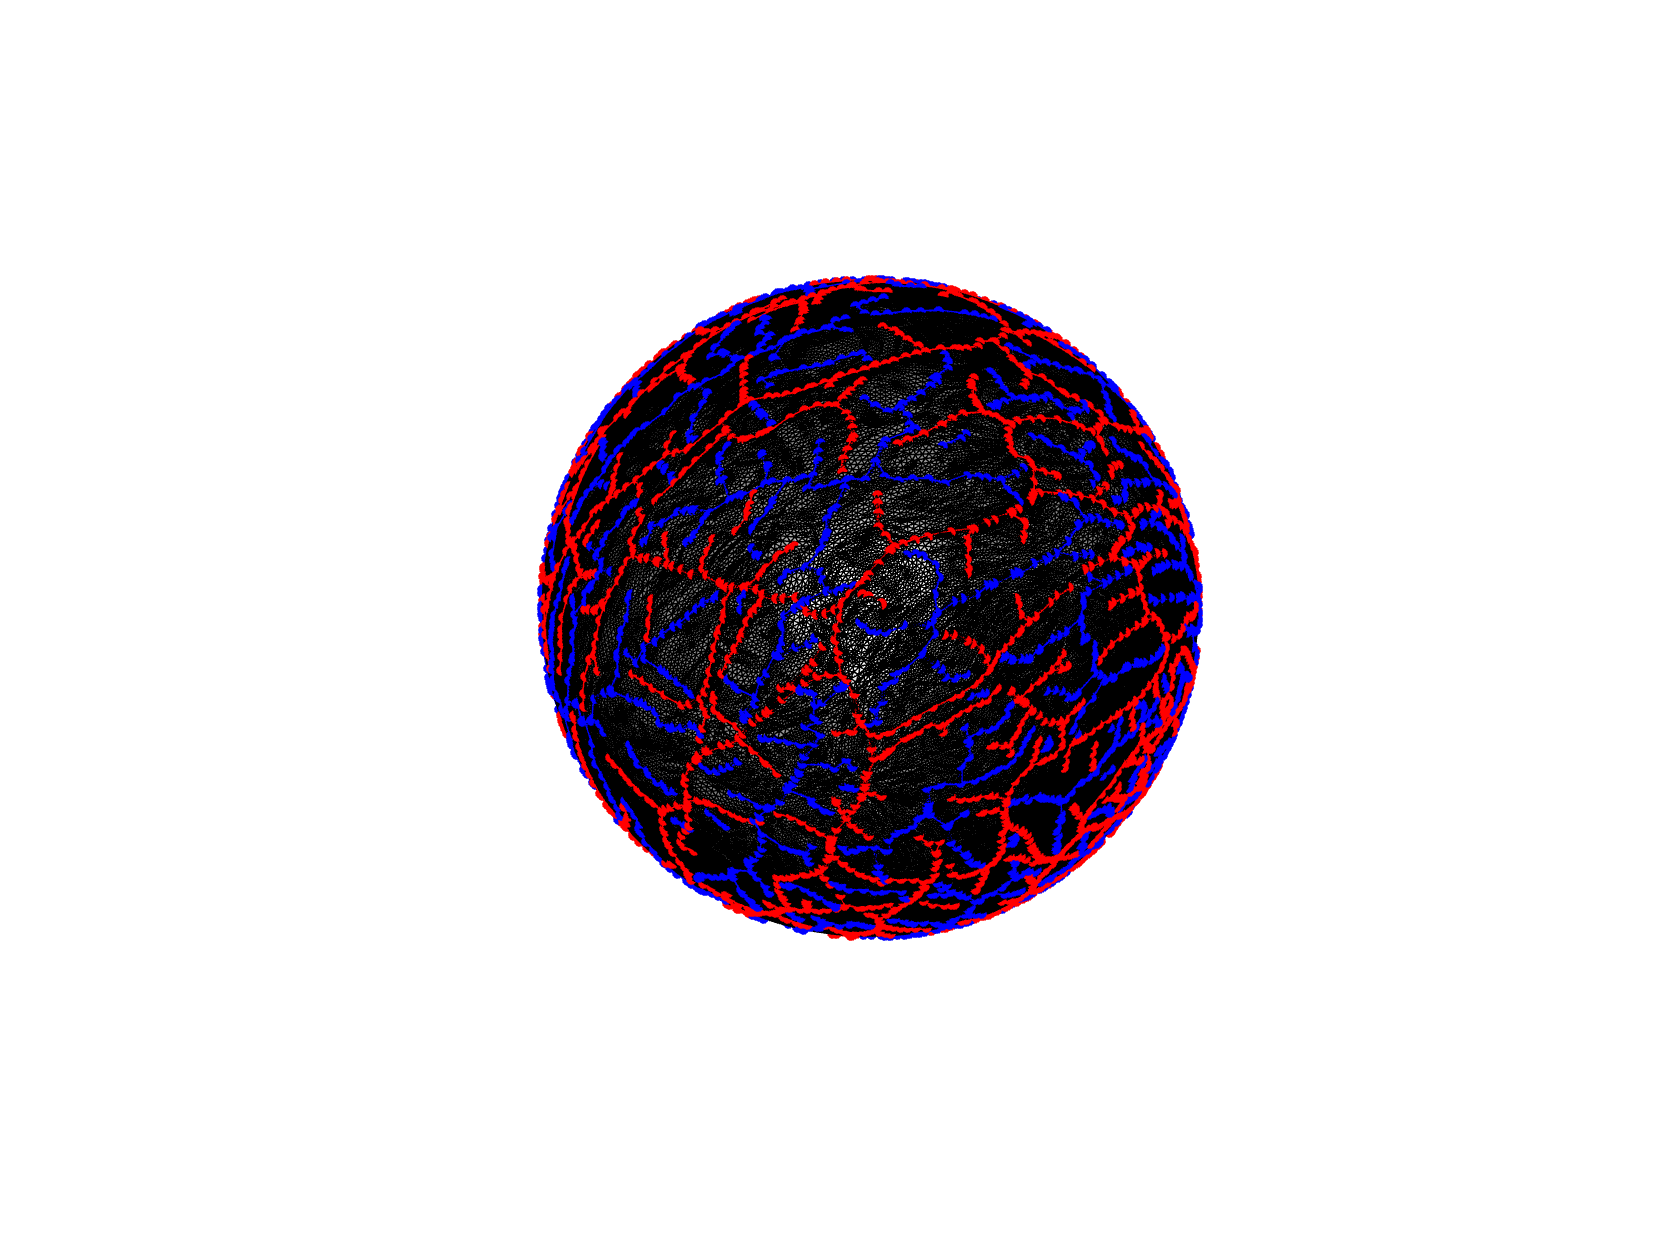

%Let's investigate the spherical mesh more carefully
surface_display_mono(sphereL,'k')
hold on; scurve_display(sphereL, gcurve,'r', 1.5) %display gyral graph edges
hold on; scurve_displaynodes(sphereL, gcurve,'r',3) %display graph nodes
hold on; scurve_display(sphereL, scurve, 'b', 1.5) %display sulcal graphs
hold on; scurve_displaynodes(sphereL, scurve,'b',3) %display graph nodes

## Sulcal pattern as trees

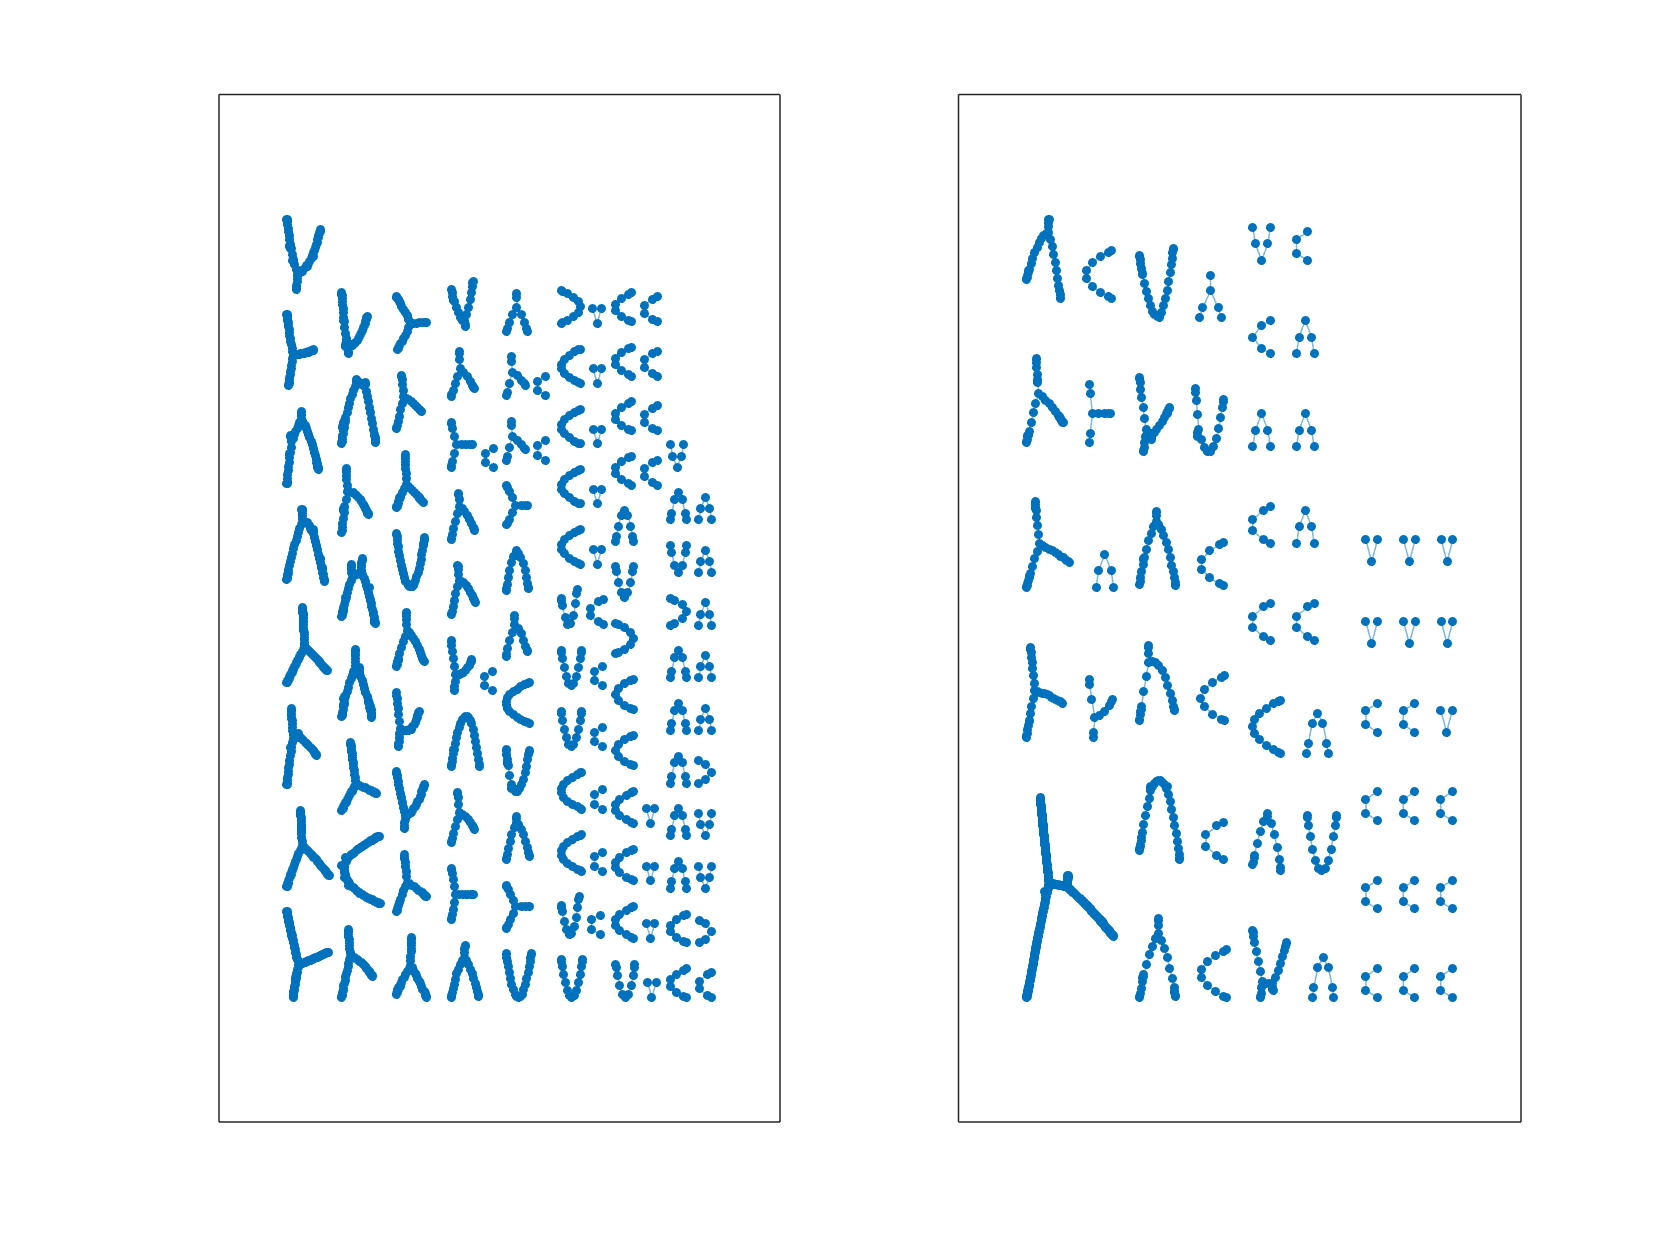

%Sulcal/gyral curves to graph data
Gscurve = scurve2tree3D(scurve, whiteL);
Ggcurve = scurve2tree3D(gcurve, whiteL);
figure; subplot(1,2,1); plot(Gscurve)
subplot(1,2,2); plot(Ggcurve)


% Extract the vertex indices from Gscurve
vertexIndicesS = Gscurve.Nodes.Vertex;
vertexIndicesG = Ggcurve.Nodes.Vertex;
%size(vertexIndicesS)  %2830 
%size(vertexIndicesG)  %3086 
vertexIndices = [vertexIndicesG; vertexIndicesS] 

vertexIndices = 5916×1 uint32 column vector
    13
    47
    54
    60
    90
    94
   106
   111
   126
   140


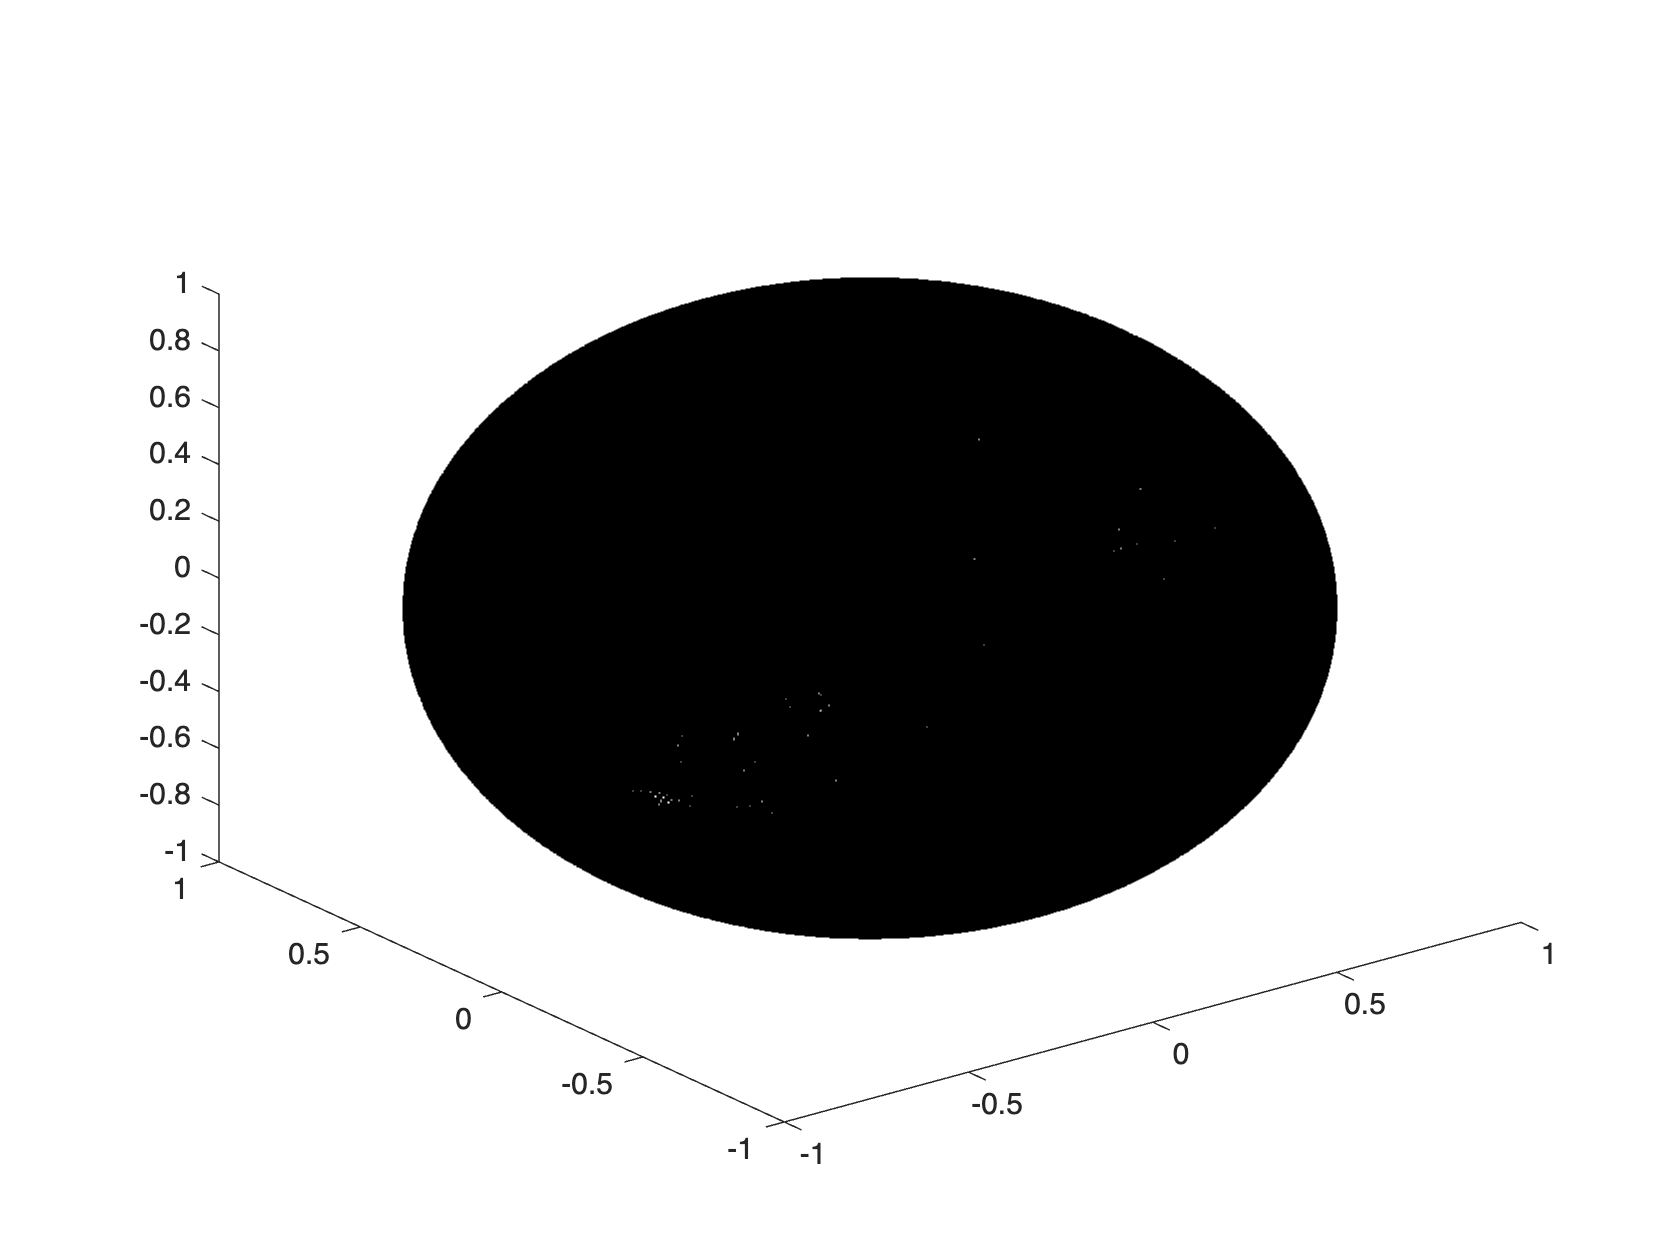

%There are a lot of triangles without data
%Let's remove triangles where there are no data. 

vertices = sphereL.vertices;
figure; plot3(vertices(:,1), vertices(:,2), vertices(:,3),'.k')

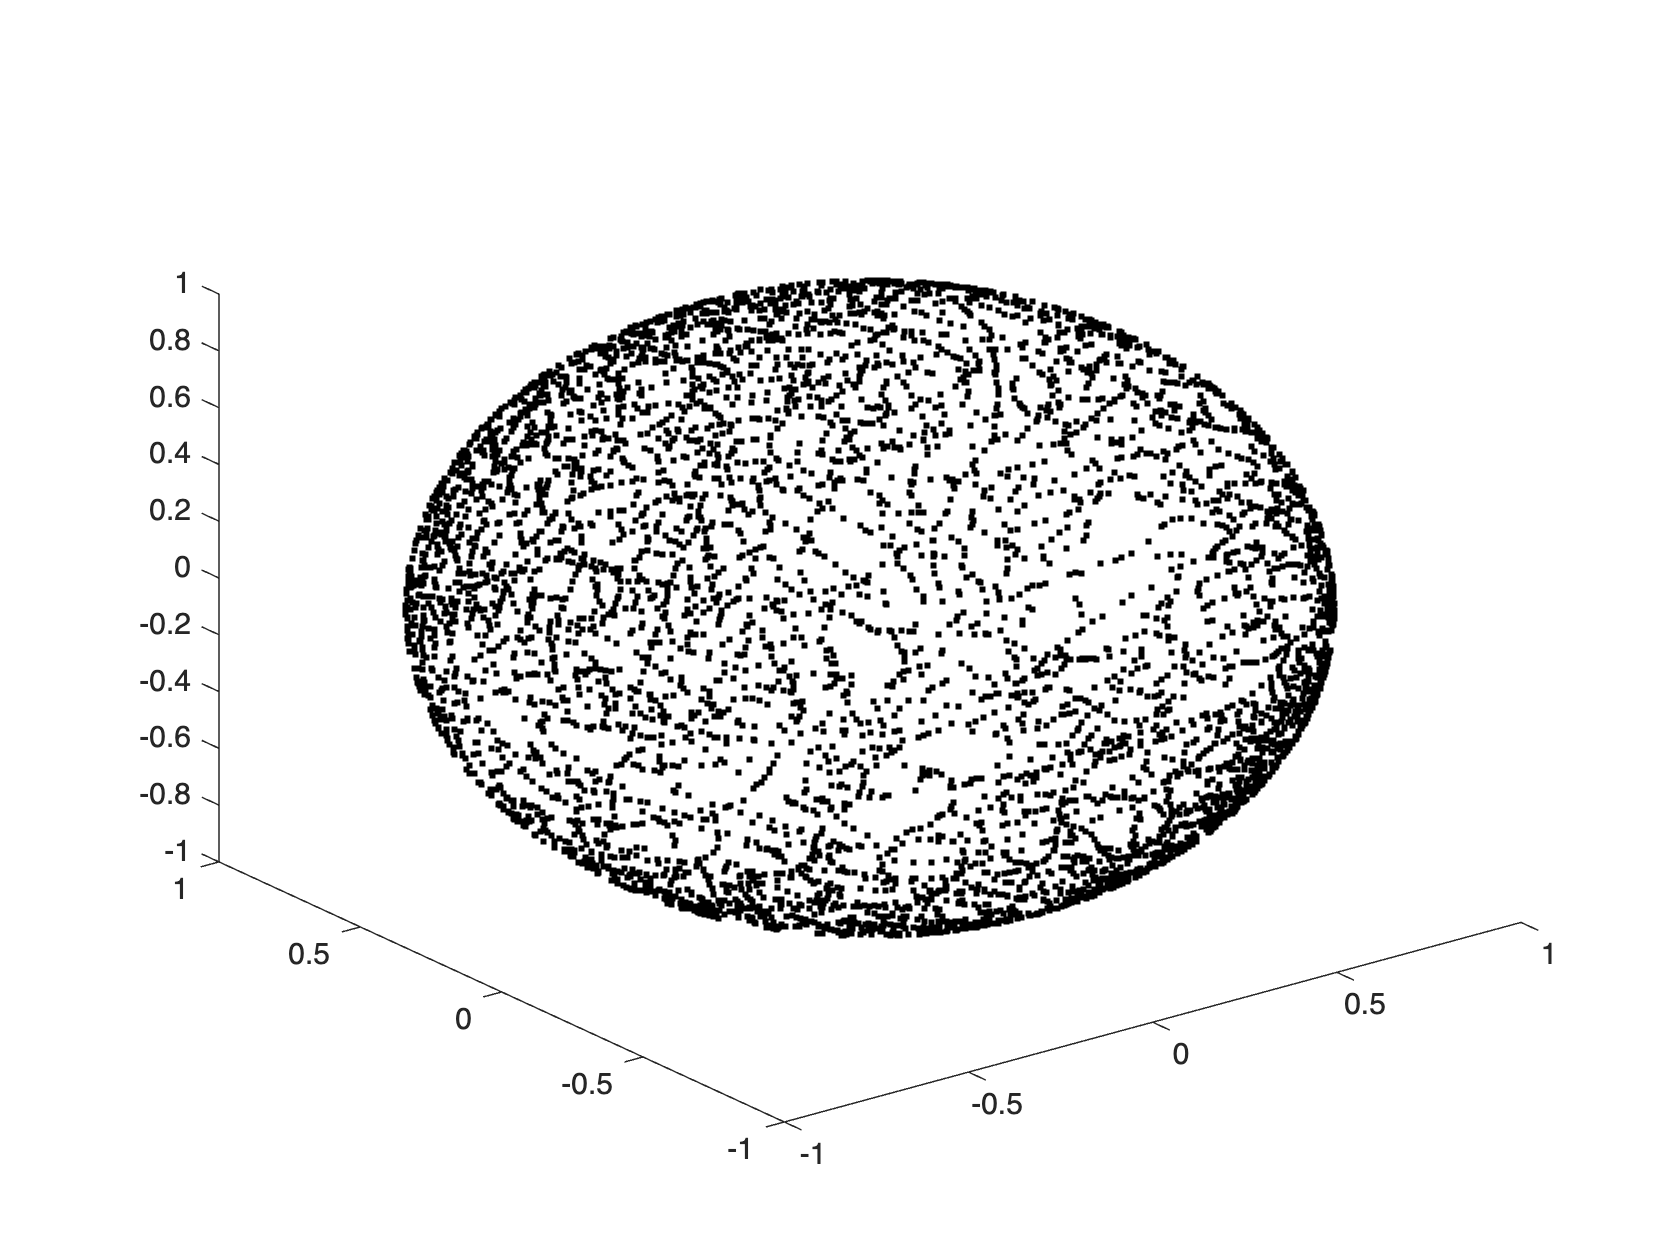


vertices_reduced = vertices(vertexIndices,:);
figure; plot3(vertices_reduced (:,1), vertices_reduced (:,2), vertices_reduced (:,3),'.k')

## Spherical Delaunay triangulation

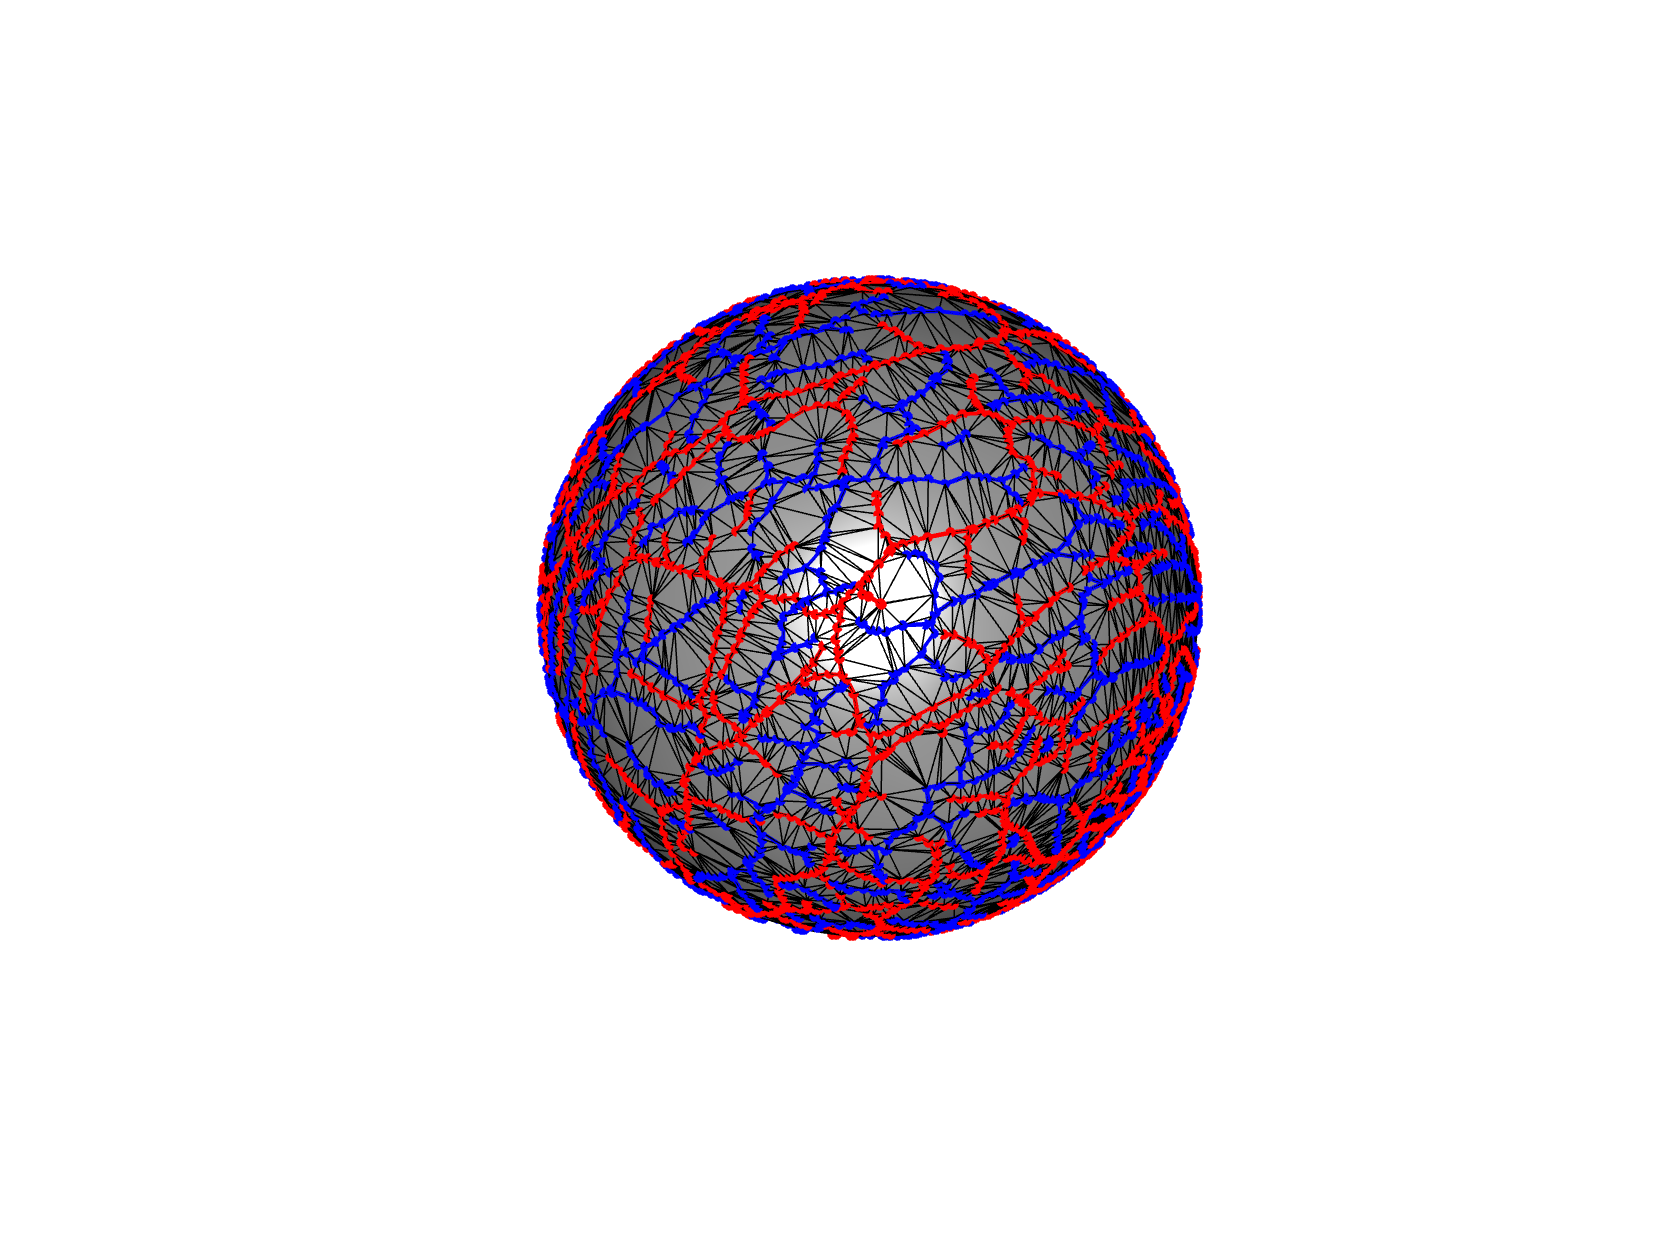

% Delaunay triangulation is most often used mesh/simplex processing
% routines to redcue the complexity of mesh/simplex. 
%
%Delaunay triangulation is a way of connecting scattered points with triangles so that the 
%triangles are as “well-shaped” as possible. It avoids long, skinny triangles by making sure that for 
% each triangle, no other point lies inside the circle drawn through its three corners. This produces 
% a clean and stable mesh and is commonly used in graphics, surface modeling, and numerical simulations.

sphere_reduced = sphere_delaunay(vertices_reduced );
surface_display_mono(sphere_reduced,'k')
hold on; scurve_display(sphereL, gcurve,'r', 1.5) %display gyral graph edges
hold on; scurve_displaynodes(sphereL, gcurve,'r',3) %display graph nodes
hold on; scurve_display(sphereL, scurve, 'b', 1.5) %display sulcal graphs
hold on; scurve_displaynodes(sphereL, scurve,'b',3) %display graph nodes